%% PIZZA COOLING SIMULATOR 🍕
% ES115 – Engineering Computer Applications
% Module 2: Physics Application
%
% Purpose:
%   Model how a hot slice of pizza cools over time using Newton's Law of Cooling.
%
% Input:
%   Initial pizza temperature, room temperature, cooling constant, time step
%
% Output:
%   Plot of temperature vs. time and safe eating time
%
% Engineering Algorithm:
%   1. Define constants
%   2. Create time array
%   3. Use Euler method to update temperature
%   4. Use if/elseif/else to classify temperature zones
%   5. Find when pizza reaches safe eating temperature
%   6. Validate that the model approaches room temperature

clear; clc; close all;

%% PARAMETERS
T_initial = 90;      % Initial pizza temp (°C)
T_env = 10;          % Room temperature (°C)
k = 0.03;            % Cooling constant
time_end = 600;      % Total time (seconds)
dt = 1;              % Time step (seconds)
safe_temp = 50;      % Safe eating threshold (°C)

%% MATHEMATICAL MODEL
% Newton's Law of Cooling:
% dT/dt = -k(T - T_env)
%
% Euler Method:
% T_new = T_old + dt * (-k * (T_old - T_env))

%% INITIAL CONDITIONS
time = 0:dt:time_end;
T = zeros(size(time));
status = strings(size(time));
T(1) = T_initial;

%% SIMULATION LOOP
for i = 1:length(time)-1

    % Update temperature using Euler method
    T(i+1) = T(i) + dt * (-k * (T(i) - T_env));

    % Temperature safety status
    if T(i) > 70
        status(i) = "Lava - Do Not Eat";
    elseif T(i) > safe_temp
        status(i) = "Risky Bite";
    else
        status(i) = "Safe to Eat";
    end
end

%% FIND SAFE EATING TIME
safe_index = find(T < safe_temp, 1);

if ~isempty(safe_index)
    safe_time = time(safe_index);
    fprintf('Pizza is safe to eat after %.1f seconds (%.1f minutes)\n', ...
        safe_time, safe_time/60);
else
    fprintf('Pizza is still too hot after %.1f seconds.\n', time_end);
end

Pizza is safe to eat after 23.0 seconds (0.4 minutes)



%% VALIDATION / TESTING
% The model should approach room temperature over time.
final_temp = T(end);
fprintf('Final temperature after %.0f seconds: %.2f °C\n', time_end, final_temp);

Final temperature after 600 seconds: 10.00 °C


fprintf('Room temperature: %.2f °C\n', T_env);

Room temperature: 10.00 °C



if abs(final_temp - T_env) < 1
    fprintf('Validation passed: final temperature approaches room temperature.\n');
else
    fprintf('Validation note: simulation may need more time to fully reach room temperature.\n');
end

Validation passed: final temperature approaches room temperature.


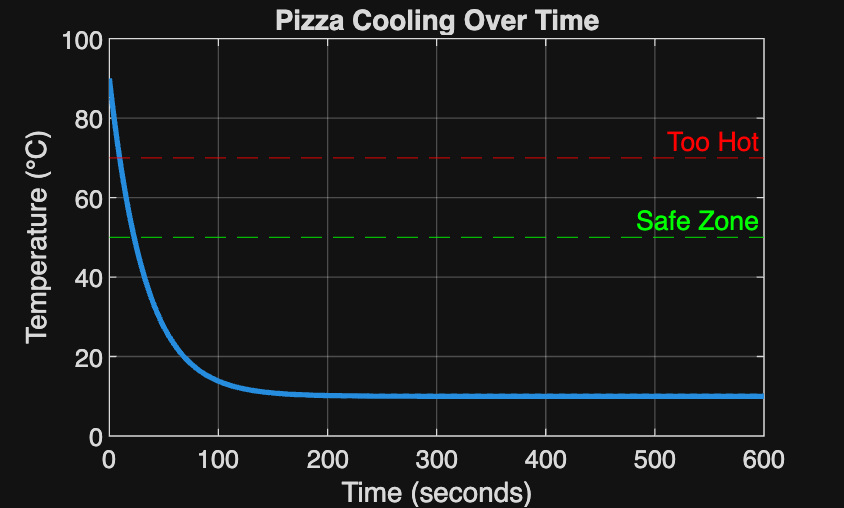


%% RESULTS PLOT
figure;
plot(time, T, 'LineWidth', 2);
xlabel('Time (seconds)');
ylabel('Temperature (°C)');
title('Pizza Cooling Over Time');
grid on;
hold on;

yline(70, '--r', 'Too Hot');
yline(safe_temp, '--g', 'Safe Zone');

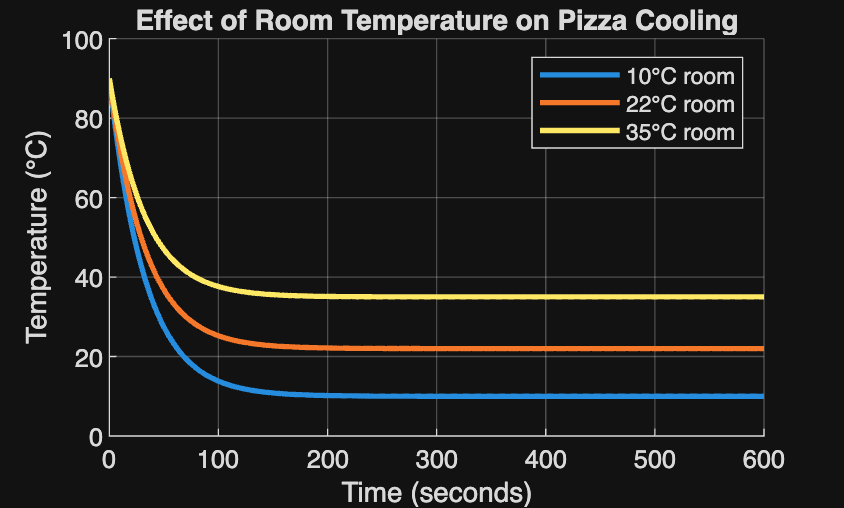


%% PARAMETER SENSITIVITY
% Compare different room temperatures
T_env_values = [10, 22, 35];

figure;
hold on;

for j = 1:length(T_env_values)
    T_test = zeros(size(time));
    T_test(1) = T_initial;

    for i = 1:length(time)-1
        T_test(i+1) = T_test(i) + dt * (-k * (T_test(i) - T_env_values(j)));
    end

    plot(time, T_test, 'LineWidth', 2);
end

xlabel('Time (seconds)');
ylabel('Temperature (°C)');
title('Effect of Room Temperature on Pizza Cooling');
legend('10°C room', '22°C room', '35°C room');
grid on;